# **CubeSat Simulation and Mission Analysis**

This live script uses the Aerospace Blockset CubeSat Simulation Library and Mapping Toolbox to analyze the mission geometry of one or more CubeSat vehicles modeled in Simulink, and determine CubeSat to ground station line-of-sight (LOS) visibility. To view the underlying MATLAB code for this report, change the display output option.

Use the individual sections of this report to:

- Define mission parameters and `'CubeSat Vehicle'` block initial conditions for simulation

- Run the specified Simulink model(s) and collect satellite telemetry

- Display the satellite trajectory over a 3D globe during the analysis window

- Display global and regional 2D ground traces during the analysis window

- Calculate and display mutual line-of-sight visibility between the CubeSat vehicle(s) and a ground station during the analysis window

- Display satellite LOS access area at the specified time of interest

- Display the satellite camera field of view (FOV) at the specified time of interest

# Mission Definition

Define mission parameters for analysis. 

### Mission start date/time:

Specify a start date for the mission.

JulianDateStart = juliandate(2019,7,1,...
                             18,0,0);
% JulianDateStart = juliandate(2019, 7, 1, 18, 0, 0);

### Mission run time:

Specify a mission duration in seconds.

AnalysisRunTime = 6*60*60;
% AnalysisRunTime = 6*60*60;

### Simulink model(s) containing '`CubeSat Vehicle'` block(s):

Specify model(s) or block path(s) as a string or cell array of strings .  All '`CubeSat Vehicle'` blocks in the specified model(s) are included in this analysis. To launch a new [CubeSat Propagation Template Model](matlab:open('asbCubeSatPropagationTemplate.sltx');), leave the field empty.

model = '';
% model = '';

#### Overwrite '`CubeSat Vehicle'` block parameters during analysis:

Specify orbital parameters to use during the mission simulation. To use current block settings, leave the fields empty. The live script ignores these settings and uses current block settings if more than one CubeSat block is present in the specified model(s). These settings are **not** pushed back to the model.

a = '6786233.13'; truelon = '';
% a = 6786233.13; truelon = [];
ecc = '0.0010537'; arglat  = '';
% ecc = 0.0010537; arglat = [];
incl = '51.7519'; lonper  = '';
% incl = 51.7519; lonper = [];
omega = '95.2562';
% omega = 95.2562;
argp = '93.4872';
% argp = 93.4872;
nu = '202.9234';
% nu = 202.9234;

# Run Simulation

Simulate the specified model. CubeSat vehicle blocks are configured to save the CubeSat position in ECEF coordinates.

   printModel = true;
%  printModel = true;

#### Current settings:

View mission definition and orbital parameter settings used in the current simulation run.

    JulianStartDate    AnalysisRunTime    SemiMajorAxis_m    Eccentricity    Inclination_deg
    _______________    _______________    _______________    ____________    _______________

        2458488             21600           6786233.13        0.0010537          51.7519    

    RAAN_deg    ArgP_deg    TrueAnomoly_deg    TrueLon_deg    ArgLat_deg    LonOfPeriapsis_deg
    ________    ________    _______________    ___________    __________    __________________

    95.2562     93.4872        302.9234             0             0                 0         



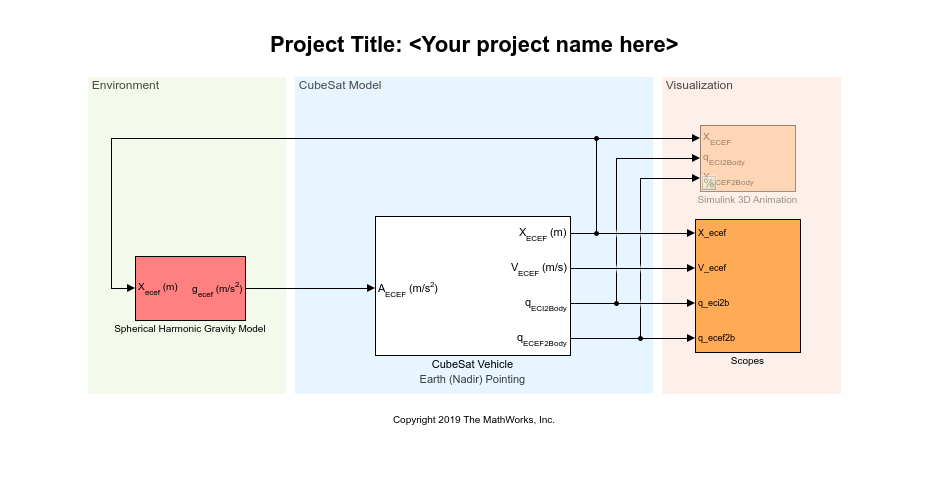

cubesatvehicle_log = logCubeSatMission(model, 'JulianStartDate', JulianDateStart,...
    'AnalysisRunTime', AnalysisRunTime, 'PrintModel', printModel,...
    'a', a, 'ecc', ecc, 'incl', incl, 'omega', omega, 'arglat', arglat,...
    'nu', nu, 'truelon', truelon, 'arglat', arglat, 'lonper', lonper,...
    'promptTemplate', true);

% find all CubeSat vehicle logs
cubesatvehicle_log = find(cubesatvehicle_log, '-regexp', 'Name', 'pos_ecef_cubesat*');
% number of cubesat vehicles present
clear cubesat
numCubeSats = numElements(cubesatvehicle_log);
for idx = numCubeSats:-1:1
    out_ecef = cubesatvehicle_log{idx};
    t_elapsed = seconds(out_ecef.Values.Time);
    cubesat(idx).blockpath= string(convertToCell(out_ecef.BlockPath));
    cubesat(idx).time_s = datetime(JulianDateStart,'ConvertFrom','juliandate') + t_elapsed;
    cubesat(idx).pos_ecef_m = out_ecef.Values.Data;

#### Logged CubeSat position data:

Preview first 10 rows of latitude (deg), longitude (deg), and altitude (m) data for each CubeSat vehicle in the specified model.

    latlonalt = ecef2lla(cubesat(idx).pos_ecef_m);
    cubesat(idx).llaTable = timetable(cubesat(idx).time_s,...
        latlonalt(:,1), latlonalt(:,2), latlonalt(:,3),...
        'VariableNames', {'lat','lon', 'alt'});
    cubesat(idx).llaTable.Properties.VariableUnits = {'deg', 'deg', 'm'};
end

untitled/CubeSat Vehicle


            Time                   lat                  lon                 alt       
    ____________________    _________________    _________________    ________________

    01-Jul-2019 18:00:00    -44.8024864258914    -145.331911703636    425256.916300626
    01-Jul-2019 18:00:01    -44.7708236201289    -145.257027549933    425241.953478386
    01-Jul-2019 18:00:02    -44.7391062315166     -145.18223005022    425226.968162942
    01-Jul-2019 18:00:03    -44.7073341215347    -145.107518604377    425211.960272913
    01-Jul-2019 18:00:04    -44.6755074065983    -145.032893166839    425196.929863961
    01-Jul-2019 18:00:05    -44.6436262047811    -144.958353694969    425181.876993338
    01-Jul-2019 18:00:06    -44.6116906340431   

for idx = 1: numCubeSats
    disp(cubesat(idx).blockpath)
    % display first 10 rows
    disp(head(cubesat(idx).llaTable, 10))
    fprintf('\n');
end

# Mission Analysis Results

### Run mission analysis and plot results:

Specify the latitude and longitude of a ground station to use in access analysis.

GS_lat =  42;
% GS_lat = 42;
GS_lon = -71;
% GS_lon = -71;

Explore different visualizations of the logged CubeSat data in the context of the defined mission. To open a figure in a separate window, click the arrow in the upper right corner of the figure.

### 3D trajectory visualization:

View the satellite orbit over the 3D globe:

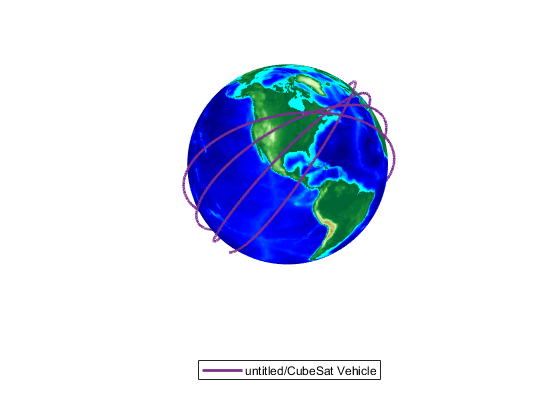

% plot topography over WGS84 ellipsoid
figure
axesm('globe','Geoid', wgs84Ellipsoid);
axis off;
colmap = colormap('lines');
colmap(1:3,:) = [];
topo_data = load('topo.mat');
[plat,plon] = meshgrat(topo_data.topo,topo_data.topolegend);
surfacem(interpn(plat), interpn(plon), interp2(topo_data.topo))
demcmap(topo_data.topo)
view(-5,23)
% define color map for multiple cubesat case
clear ax
for idx = numCubeSats:-1:1
    % plot trajectory(s)
    ax(idx) = plot3m(cubesat(idx).llaTable.lat, cubesat(idx).llaTable.lon,...
        cubesat(idx).llaTable.alt, '-','Color', colmap(idx,:), 'LineWidth', 2);
end
legend(ax, {cubesat.blockpath}, 'Location','southoutside');

### 2D ground track visualization:

View the ground trace as a 2D projection:

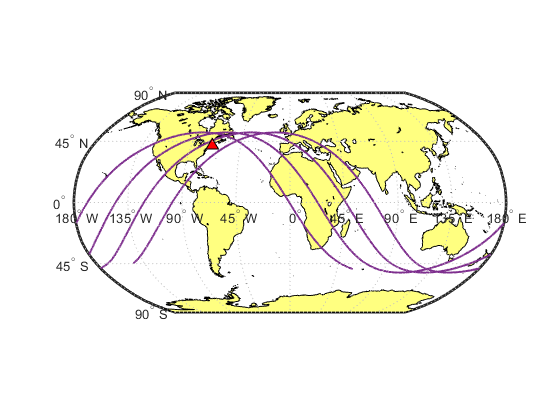

% plot world map with land areas
figure
worldmap('World')
geoshow('landareas.shp')
for idx = 1: numCubeSats
    % plot ground track(s)
    plotm(cubesat(idx).llaTable.lat, cubesat(idx).llaTable.lon,...
        'Color', colmap(idx,:), 'LineWidth', 1.5)
end
% plot ground station
plotm(GS_lat,GS_lon,'k^','MarkerSize',8,'MarkerFaceColor','r')

View regional ground trace.  Select the region of interest from the dropdown menu:

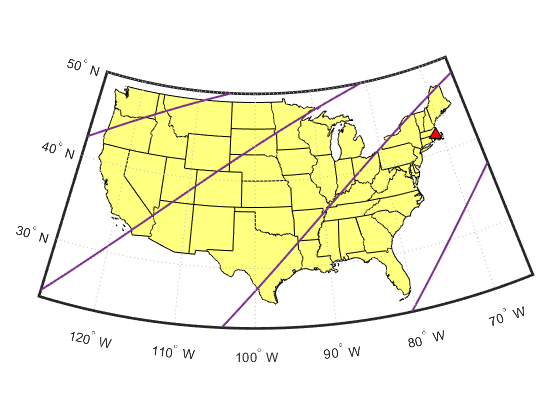

region = "usa";
% region = 'usa';

ax_region = plotRegion(GS_lon, GS_lat, region);
if exist('ax_region', 'var') && ~isempty(ax_region)
    % plot ground track(s)
    for idx = 1: numCubeSats
        plotm(cubesat(idx).llaTable.lat, cubesat(idx).llaTable.lon,...
            'Color', colmap(idx,:), 'LineWidth', 1.5)
    end
    % plot ground station
    plotm(GS_lat,GS_lon,'k^','MarkerSize',8,'MarkerFaceColor','r')
end

### CubeSat to ground station line-of-sight visibility:

Compute mutual visibility (access) between the ground station defined above and the satellite throughout the analysis window. From the LOS Method drop down list, specify that the line-of-sight (LOS) between the two points be calculated using spherical Earth geometry or with the inclusion of topographical data. The access results overlay a 2D ground trace of the satellite's trajectory.

losOption = "spherical";
% losOption = 'spherical';

minLat = GS_lat; maxLat = GS_lat;
minLon = GS_lon; maxLon = GS_lon;
% find access intervals
clear textPos
for idx = numCubeSats:-1:1
    % find LOS visibility properties and create table
    [cubesat(idx).accessTable, inView] = generateAccessTable(...
        cubesat(idx).time_s, [cubesat(idx).llaTable.lat...
        cubesat(idx).llaTable.lon cubesat(idx).llaTable.alt],...
        [GS_lat GS_lon], losOption);
    if any(contains(cubesat(idx).llaTable.Properties.VariableNames, 'inView'))
        % update in-view data
        cubesat(idx).llaTable.inView = inView;
    else
        % add in-view data to table
        cubesat(idx).llaTable = addvars(cubesat(idx).llaTable, inView,...
            'NewVariableNames', 'inView');
    end
    % Get position of pass number labels to plot
    [textPos{idx}, maxLat, minLat, maxLon, minLon] = getTextPos(...
        cubesat(idx).accessTable, maxLat, minLat, maxLon, minLon);
end


Preview first 10 rows CubeSat latitude (deg), longitude (deg), and altitude (m) data with new visibility column: 

% display lla table with visibilty column
for idx = 1: numCubeSats
    disp(cubesat(idx).blockpath)
    disp(head(cubesat(idx).llaTable, 10)) % display first 10 rows
    fprintf('\n');
end

untitled/CubeSat Vehicle


            Time                   lat                  lon                 alt           inView
    ____________________    _________________    _________________    ________________    ______

    01-Jul-2019 18:00:00    -44.8024864258914    -145.331911703636    425256.916300626    false 
    01-Jul-2019 18:00:01    -44.7708236201289    -145.257027549933    425241.953478386    false 
    01-Jul-2019 18:00:02    -44.7391062315166     -145.18223005022    425226.968162942    false 
    01-Jul-2019 18:00:03    -44.7073341215347    -145.107518604377    425211.960272913    false 
    01-Jul-2019 18:00:04    -44.6755074065983    -145.032893166839    425196.929863961    false 
    01-Jul-2019 18:00:05    -44.6436262047811   

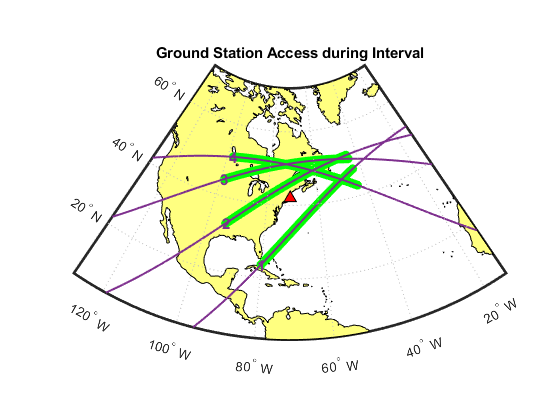

untitled/CubeSat Vehicle


           start                    stop            duration         lat               lon               alt             losDist        closestApproach 
    ____________________    ____________________    ________    ______________    ______________    ______________    ______________    ________________

    01-Jul-2019 18:24:13    01-Jul-2019 18:34:18    00:10:05    [606×1 double]    [606×1 double]    [606×1 double]    [606×1 double]    881345.234687831
    01-Jul-2019 20:00:24    01-Jul-2019 20:11:04    00:10:40    [641×1 double]    [641×1 double]    [641×1 double]    [641×1 double]    592768.530001633
    01-Jul-2019 21:38:06    01-Jul-2019 21:47:52    00:09:46    [587×1 double]    [587×1 double]    [587×1 double] 

% get bounds for plot
[latlim2, lonlim2] = calcLatLonLim(maxLat, minLat, maxLon, minLon);
% plot access
if ~all(cellfun(@isempty, {cubesat.accessTable}))
    figure
    title("Ground Station Access during Interval");
    % plot world map between bounds with land areas
    worldmap(latlim2,lonlim2);
    geoshow('landareas.shp')
    for idx = 1: numCubeSats
        for jdx = 1:height(cubesat(idx).accessTable)
            % plot access intervals
            plotm(cubesat(idx).accessTable.lat{jdx},cubesat(idx).accessTable.lon{jdx},...
            'og', 'MarkerFaceColor','g')
            % plot pass number label
            textm(textPos{idx}{jdx}(1),textPos{idx}{jdx}(2),...
                num2str(jdx), 'Color', colmap(idx,:), 'HorizontalAlignment','center',...
                'FontUnits', 'normalized', 'FontSize', .055, 'FontWeight', 'bold')
        end
    end
    % plot ground station
    plotm(GS_lat,GS_lon,'k^','MarkerSize',8,'MarkerFaceColor','r')
    for idx = 1: numCubeSats
        % plot ground track
        plotm(cubesat(idx).llaTable.lat, cubesat(idx).llaTable.lon,...
            'Color', colmap(idx,:), 'LineWidth', 1.5)
    end

View CubeSat access interval start and stop times, interval durations, position data, LOS distances, and closest approach:

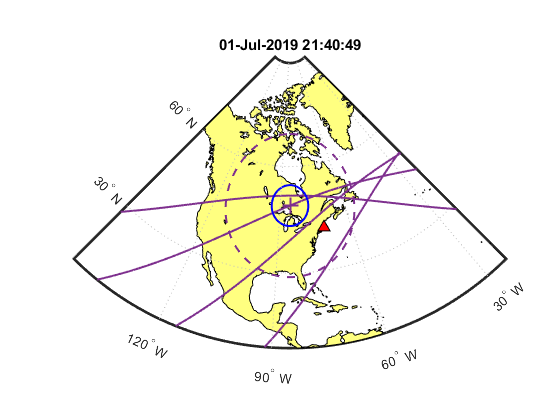

    % display access table
    for idx = 1: numCubeSats
        disp(cubesat(idx).blockpath)
        if ~isempty(cubesat(idx).accessTable)
            disp(cubesat(idx).accessTable, 15)
        else
            warning('No ground station access intervals identified for this vehicle.')
        end
        fprintf('\n');
    end
else
    warning('No ground station access windows identified in the simulation data.')
    % plot world map with land areas
    figure
    worldmap('World')
    geoshow('landareas.shp')
    title("Ground station access during Interval");
    % plot ground station
    plotm(GS_lat,GS_lon,'k^','MarkerSize',8,'MarkerFaceColor','r')
    for idx = 1: numCubeSats
        % plot ground track
        plotm(cubesat(idx).llaTable.lat, cubesat(idx).llaTable.lon,...
            'Color', colmap(idx,:), 'LineWidth', 1.5)
    end
end

### CubeSat access area at time of interest (TOI):

Compute satellite access area and nadir-pointed camera FOV at the specifed time of interest using the notation: 

- **+ **- Sub-satellite position

- Dashed circle - Satellite access area

- Solid blue circle - Field-of-view of a nadir-pointed onboard camera. To exclude from plotting, leave half angle field empty.

TOI = datetime(2019,7,1,... 

cubesat = struct with fields:
      blockpath: "untitled/CubeSat Vehicle"
         time_s: [21601×1 datetime]
     pos_ecef_m: [21601×3 double]
       llaTable: [21601×4 timetable]
    accessTable: [4×8 table]
       toiTable: [1×4 timetable]


               21,40,49);    
% TOI = datetime(2019,7,1,21,40,49);
eta = '55';
% eta = 45; deg
 
if exist('TOI','var') && ~isnat(TOI)
    minLat = GS_lat; maxLat = GS_lat;
    minLon = GS_lon; maxLon = GS_lon;
    clear satview_lats satview_lons
    for idx = numCubeSats:-1:1
        % find TOI index in LLA data
        [toiDist, toiIndex] = min(abs(cubesat(idx).llaTable.Time-TOI));
        cubesat(idx).toiTable = cubesat(idx).llaTable(toiIndex,:);
        cubesat(idx).toiTable.Properties.DimensionNames{1} = 'TimeOfInterest';
        if toiDist > seconds(5)
            warning(['Time of interest not found in logged data for CubeSat ''%s''.',...
                ' Using closest value: %s.'], cubesat(idx).blockpath,...
                string(cubesat(idx).toiTable.TimeOfInterest));
        end
        % calculate access area
        h = cubesat(idx).toiTable.alt;
        r = sqrt(sum((cubesat(idx).pos_ecef_m(toiIndex,:)).^2,2))-h;
        lambda0  = acosd(r/(r+h));
        [satview_lats{idx}, satview_lons{idx}] = scircle1(cubesat(idx).toiTable.lat,...
            cubesat(idx).toiTable.lon,lambda0);
        % determine latlon limits for plot
        minLat = min([satview_lats{idx}; minLat]);
        maxLat = max([satview_lats{idx}; maxLat]);
        minLon = min([satview_lons{idx}; minLon]);
        maxLon = max([satview_lons{idx}; maxLon]);
    end
    % get bounds for plot
    [latlim3, lonlim3] = calcLatLonLim(maxLat, minLat, maxLon, minLon);
    % plot world map between bounds with land areas
    figure
    ax_FOV = worldmap(latlim3, lonlim3);
    geoshow('landareas.shp')
    daspect([1 1 1])
    title(string(TOI))
    for idx = 1: numCubeSats
        % Plot ground trace
        plotm(cubesat(idx).llaTable.lat,cubesat(idx).llaTable.lon, 'Color', colmap(idx,:),...
            'LineWidth',1.5)
        % Plot access area
        plotm(satview_lats{idx},satview_lons{idx}, '--', 'Color', colmap(idx,:), 'LineWidth',1.5)
        % Plot subsatellite point
        plotm(cubesat(idx).toiTable.lat, cubesat(idx).toiTable.lon,...
            '+', 'Color', colmap(idx,:), 'MarkerSize',12, 'LineWidth',1.5)
    end
    % plot ground station
    plotm(GS_lat,GS_lon,'k^','MarkerSize',8,'MarkerFaceColor','r')
    
    % camera FOV
    if ~isempty(eta)
        eta = str2double(eta);
        r_e = earthRadius('m');
        for idx = 1: numCubeSats
            % calculate  angular radius of Earth as seen from the satellite
            rho = asind(r_e/(r_e+cubesat(idx).toiTable.alt)); % deg
            % calculate satellite elevation angle
            epsilon = acosd(sind(eta)/sind(rho)); % deg
            % calculate angular radius of camera FOV measured from Earth center
            lambda = 90 - eta - epsilon; % deg
            % plot FOV
            if isreal(epsilon)
                [lat_FOV, lon_FOV] = scircle1(cubesat(idx).toiTable.lat,cubesat(idx).toiTable.lon,lambda);
            else % FOV extends beyond horizon
                lat_FOV = satview_lats{idx}; 
                lon_FOV = satview_lons{idx};
            end
            plotm(lat_FOV, lon_FOV,'b','LineWidth',1.5, 'Parent', ax_FOV);
        end
    end
else
    disp('No valid TOI provided.');
end

# Further Analysis

To view and interact with the various data tables that were created during this analysis, access the `cubesat` structure in the base workspace.

cubesat

function lat = wrapTo90(lat)
%WRAPTO90 Wrap angle in degrees to [-90 90]
q = (lat < -90) | (90 < lat);
lat2 = lat(q) + 90;
positiveInput = (lat2 > 0);
lat2 = mod(lat2, 180);
lat2((lat2 == 0) & positiveInput) = 180;
lat(q) = lat2-90;
end

function [latlim, lonlim] = calcLatLonLim(maxLat, minLat, maxLon, minLon)
%CALCLATLONLIM Get latlon bounding box for world map plot
if abs(minLat - 90) < 15 % Plot North Pole
    latlim = [60 90];
    lonlim = [minLon maxLon+360]+180;
elseif abs(maxLat + 90) < 15 % Plot South Pole
    latlim = [-90 -60];
    lonlim = [minLon maxLon+360]+180;
else % Plot ground station region
    latlim = wrapTo90([max(minLat-20,-90), min(maxLat+20,90)]);
    lonlim = wrapTo180([minLon-30, maxLon+30]);
    if sum(abs(lonlim)) > 300
        latlim = [-90 90];
        lonlim = [-180 180];
    end
end
end

function ax_region = plotRegion(GS_lon, GS_lat, region)
%PLOTREGION Plot world map using provided region
switch region
    case 'groundstation'
        [latlim, lonlim] = calcLatLonLim(GS_lat, GS_lat, GS_lon, GS_lon);
        figure
        ax_region = worldmap(latlim,lonlim);
        geoshow('landareas.shp')
    case 'usa'
        figure
        ax_region = usamap('conus');
        statesshp = shaperead('usastatehi', 'UseGeoCoords', true);
        geoshow(statesshp)
    case {'Africa', 'Antarctica', 'Asia', 'Australia', 'Eurasia', 'Europe',...
            'North America', 'South America', 'North Pole', 'South Pole'}
        figure
        ax_region = worldmap(region);
        worldshp = shaperead('landareas.shp', 'UseGeoCoords', true);
        geoshow(worldshp)
    case 'other'
        figure
        ax_region = worldmap;
        if ~isempty(ax_region)
            worldshp = shaperead('landareas.shp', 'UseGeoCoords', true);
            geoshow(worldshp)
        end
end
end

function [textPos, maxLat, minLat, maxLon, minLon] = getTextPos(...
    accessTable, maxLat, minLat, maxLon, minLon)
%GETTEXTPOS Determine suitable locations for access interval index overlay.
% Label will overlay last latlon pair in access interval unless there is an 
% overlap, in which case label will display on first latlon pair
textPos = [];
if ~isempty(accessTable)
    minLat = min(vertcat(accessTable.lat{:}, minLat));
    maxLat = max(vertcat(accessTable.lat{:}, maxLat));
    minLon = min(vertcat(accessTable.lon{:}, minLon));
    maxLon = max(vertcat(accessTable.lon{:}, maxLon));
    latEnds = cellfun(@(x) x(end), accessTable.lat);
    lonEnds = cellfun(@(x) x(end), accessTable.lon);
end

% Is there overlap
overlap = false;
if height(accessTable) > 1
    checkDist = cell2mat(arrayfun(@(x) distance(latEnds(x),...
        lonEnds(x), latEnds(1:end ~= x),...
        lonEnds(1:end ~= x)), 1:height(accessTable),...
        'UniformOutput', false)');
    if any(checkDist < 4)
        overlap = true;
    end
end
for jdx = height(accessTable):-1:1
    if overlap
        textPos{jdx} = [accessTable.lat{jdx}(1),...
            accessTable.lon{jdx}(1)];
    else
        textPos{jdx}= [accessTable.lat{jdx}(end),...
            accessTable.lon{jdx}(end)];
    end
end
end

# References

[1] Wertz, James R, David F. Everett, and Jeffery J. Puschell. *Space Mission Engineering: The New Smad*. Hawthorne, CA: Microcosm Press, 2011. Print.

*Copyright 2019 The MathWorks, Inc.*